
% figure C v.s. R_BT %

clear all;
close all;

load('E:\Comagnetometer_Pub\curvature_simulation\curvature.mat');



% angle_list=[0:1:2].*1e-5;
% B_list=[0.1 1 2 3 3.4 3.7 3.9 3.95 3.96 3.998 3.9985 3.999 4 4.0007 4.0015 4.002 4.05 4.1 4.2 4.5 5 6 7 7.97 10 13 16 20 25 30 50 100 200];
% %B_list=[3.9:0.01:4.1];
% 
% for k1 = 1:length(B_list)
%     for k2 = 1:length(angle_list)
%         [f_mean(k2),f_std(k2)] = BscanXZ(angle_list(k2),B_list(k1)); 
%     end
%     curvature(k1) = (2*pi*(f_mean(3)-f_mean(2))-(f_mean(2)-f_mean(1)))/B_list(k1)*1e10;
% end


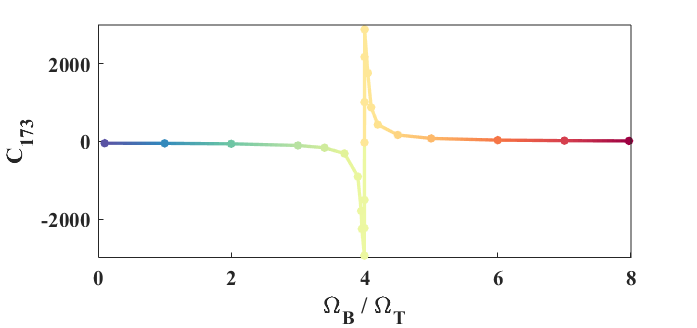


f1 = figure;
hold on;
cMap = getPyPlot_cMap('Spectral',128,0,"C:\Users\USTC\AppData\Local\Programs\Python\Python313\python");

delete = 18;
cMap(64-delete/2+1:64+delete/2,:) = [];
temp = cMap';
temp = fliplr(temp);
cMap1 = temp';
colormap(cMap1);

colors = B_list;
%colors = atan((B_list-4.00)*5);

patch([B_list,NaN],[curvature,NaN],[colors,NaN],...
    'LineWidth',2.5,'EdgeColor','interp',...
    'Marker','o','MarkerSize',4,'MarkerFaceColor','flat');

clim([0 8]);

%colorbar;

x_low = 0;
x_high = 8;
y_low = -3000;
y_high = 3000;

xlim([x_low x_high]);
ylim([y_low y_high]);
xticks([0 2 4 6 8]);
yticks([-2 0 2]*1e3);

set(gca,'FontName','Times New Roman','FontSize',16,'FontWeight','bold');

xlabel('\Omega_B / \Omega_T','FontName','Times New Roman');
ylabel('C_{173}','FontName','Times New Roman');

grid off;
box off;

plot([x_low x_high],[y_high y_high],'Color',[0.15 0.15 0.15]);
plot([x_high x_high],[y_low y_high],'Color',[0.15 0.15 0.15]);

set(f1,'Visible','on','Position',[137,523,697,328]);


savefig(f1,'E:\Comagnetometer_Pub\curvature_simulation\curvature.fig');
saveas(f1,'E:\Comagnetometer_Pub\curvature_simulation\curvature.png');
saveas(f1,'E:\Comagnetometer_Pub\curvature_simulation\curvature.eps','psc');
saveas(f1,'E:\Comagnetometer_Pub\curvature_simulation\curvature.svg');


save('E:\Comagnetometer_Pub\curvature_simulation\curvature.mat');

function [f_mean,f_std]=BscanXZ(angle,Bz)

%clear all;
%close all;
colors = npg(100);
F=5/2;
sigmax = spinOp(F,'x');
sigmay = spinOp(F,'y');
sigmaz = spinOp(F,'z');


%% 输入变量
start_point = 800;   % 不分析前几个周期
N = 1200;   % 共计N个周期
dN = 0.15;   % 计算步长为dN个周期

initial_angle = 0;   % 初始偏离理想极化

%angle = 3/400;   % 横向磁场角度
tensor = 1;   % tensor shift大小
%Bz = 50;   % Frequency量纲

phase0 = 0.5*pi;  % 第一次过零点前经历的相位


ham0 = 1*sigmax+1*sigmax^2;
ham1 = 2*pi*( (angle*sigmay+sigmaz)*Bz/sqrt(1+angle^2) + tensor*sigmaz^2);   % omega量纲

freq_center = Bz*F/0.5;   % Frequency量纲

initial_0 = zeros(2*F+1,1);
initial_0(1) = 1;
initial_0 = ham_evolve(sigmax+sigmax^2,initial_0,initial_angle);
initial = ham_evolve(ham1,initial_0,0.75*78/108/freq_center);
initial = ham_evolve(ham0,initial,pi/2);
%initial = ham_evolve(ham0,initial,pi/2);


timestep = dN*1/freq_center;
timestart = start_point*1/freq_center;
timeend = N*1/freq_center;
timelist = [0:timestep:timeend];


for k = 1:length(timelist)
    precess_state = ham_evolve(ham1,initial,timelist(k));
    final_state(:,k) = ham_evolve(ham0,precess_state,pi/2);
end
pop_state = abs(final_state).^2;

sz(:) = (pop_state(1,:)-pop_state(2*F+1,:))./(pop_state(1,:)+pop_state(2*F+1,:));


[contrast,cycle_n,zero_list,zero_mark] = cycle_count_function(sz,timelist,phase0);

for k = 1:length(zero_list)
    zero_state1 = ham_evolve(ham1,initial,zero_list(k));
    zero_state(:,k) = ham_evolve(ham0,zero_state1,pi/2);
end

pop_state1 = abs(zero_state).^2;
zero_sz(:) = (pop_state1(1,:)-pop_state1(2*F+1,:))./(pop_state1(1,:)+pop_state1(2*F+1,:));
zero_residual_phase = zero_sz/contrast.*zero_mark;

zero_phase = phase0+2*pi*[0:0.5:cycle_n]+zero_residual_phase;
freq_list = zero_phase./zero_list/(2*pi);
cycle_list = [phase0/(2*pi):0.5:phase0/(2*pi)+cycle_n];

freq_list(1:start_point*2) = [];
cycle_list(1:start_point*2) = [];

f_mean = mean(freq_list);
f_std = std(freq_list);



end
function final = ham_evolve(ham,initial,time)
try
    final = expm(-1i*ham.*time)*initial;
catch 
    disp("Wrong Solution!!");
end
end
